# PR09.

- García Muñoz Ari Manuel

- Morales Flores Pedro Martín

- Pérez Medina Rafael

- Pineda Marin Ulises

- Salazar Garcia Daniel

## E10.13

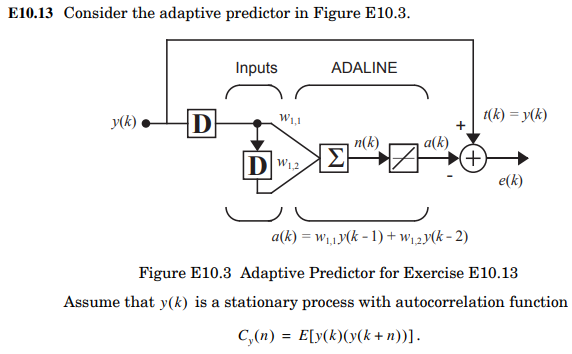

Si tenemos que

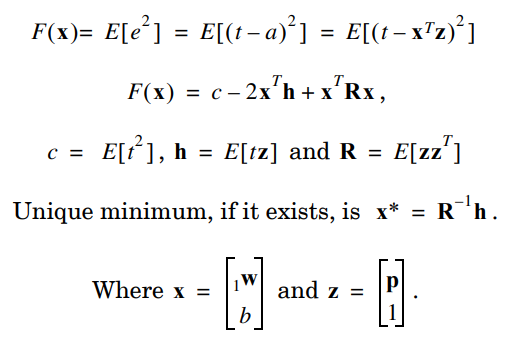

Como $y\left(k\right)=t\left(k\right):$

$E\left\lbrack y\left(k\right)y\left(k+n\right)\right\rbrack \;\textrm{cuando}\;n=0$: $E\left\lbrack y\left(k\right)y\left(k\right)\right\rbrack =E\left\lbrack y^2 \left(k\right)\right\rbrack =E\left\lbrack t^2 \left(k\right)\right\rbrack :E\left\lbrack t^2 \right\rbrack =c$

Que entonces c es $C_y \left(0\right)$.


$$\begin{array}{l}
E\left\lbrack \textrm{tz}\right\rbrack =\\
E\left\lbrack \left\lbrack y\left(k\right)\right\rbrack *\left\lbrack \begin{array}{c}
y\left(k-1\right)\\
y\left(k-2\right)
\end{array}\right\rbrack \right\rbrack \\
E\left\lbrack \begin{array}{c}
y\left(k\right)y\left(k-1\right)\\
y\left(k\right)y\left(k-2\right)
\end{array}\right\rbrack =E\left\lbrack \begin{array}{c}
C_y \left(1\right)\\
C_y \left(2\right)
\end{array}\right\rbrack 
\end{array}$$


Por lo que $h=E\left\lbrack \begin{array}{c}
C_y \left(1\right)\\
C_y \left(2\right)
\end{array}\right\rbrack$ 


$$\begin{array}{l}
E\left\lbrack zz^t \right\rbrack =\\
E\left\lbrack \left\lbrack \begin{array}{c}
y\left(k-1\right)\\
y\left(k-2\right)
\end{array}\right\rbrack *\left\lbrack \begin{array}{cc}
y\left(k-1\right) & y\left(k-2\right)
\end{array}\right\rbrack \right\rbrack \\
E\left\lbrack \begin{array}{cc}
y^2 \left(k-1\right) & y\left(k-1\right)y\left(k-2\right)\\
y\left(k-1\right)y\left(k-2\right) & y^2 \left(k-2\right)
\end{array}\right\rbrack 
\end{array}$$


Se considera $E\left\lbrack \begin{array}{cc}
C_y \left(0\right) & C_y \left(1\right)\\
C_y \left(1\right) & C_y \left(0\right)
\end{array}\right\rbrack =R$

Y con $x=\left\lbrack \begin{array}{c}
w_{11} \\
w_{12} 
\end{array}\right\rbrack$

Por lo tanto

syms Cy0 Cy1 Cy2 w11 w12
x = [w11;w12];
c = Cy0

$$c = {\mathrm{Cy}}_{0}$$

h = [Cy1;Cy2]

$$h = \left(\begin{array}{c} {\mathrm{Cy}}_{1}\\ {\mathrm{Cy}}_{2} \end{array}\right)$$

R = [Cy0 Cy1;Cy1 Cy0]

$$R = \left(\begin{array}{cc} {\mathrm{Cy}}_{0} & {\mathrm{Cy}}_{1}\\ {\mathrm{Cy}}_{1} & {\mathrm{Cy}}_{0} \end{array}\right)$$

F(w11,w12) = c - 2*x'*h + x'*R*x

$$F(w11, w12) = {\mathrm{Cy}}_{0}+w_{11}\,\left({\mathrm{Cy}}_{0}\,\bar{w_{11}}+{\mathrm{Cy}}_{1}\,\bar{w_{12}}\right)+w_{12}\,\left({\mathrm{Cy}}_{0}\,\bar{w_{12}}+{\mathrm{Cy}}_{1}\,\bar{w_{11}}\right)-2\,{\mathrm{Cy}}_{1}\,\bar{w_{11}}-2\,{\mathrm{Cy}}_{2}\,\bar{w_{12}}$$

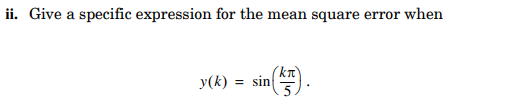

syms y(k)
Cy0 = y(k) ^2

$$Cy0 = {y\left(k\right)}^{2}$$

Cy1 = y(k)*y(k-1)

$$Cy1 = y\left(k-1\right)\,y\left(k\right)$$

Cy2 = y(k)*y(k-2)

$$Cy2 = y\left(k-2\right)\,y\left(k\right)$$

S1 = subs(F(w11,w12))

$$S1 = w_{11}\,\left(\bar{w_{11}}\,{y\left(k\right)}^{2}+y\left(k-1\right)\,\bar{w_{12}}\,y\left(k\right)\right)+w_{12}\,\left(\bar{w_{12}}\,{y\left(k\right)}^{2}+y\left(k-1\right)\,\bar{w_{11}}\,y\left(k\right)\right)+{y\left(k\right)}^{2}-2\,y\left(k-1\right)\,\bar{w_{11}}\,y\left(k\right)-2\,y\left(k-2\right)\,\bar{w_{12}}\,y\left(k\right)$$

y(k) = sin((k*pi) / 5)

$$y(k) = \sin\left(\frac{\pi \,k}{5}\right)$$

S2 = subs(S1)

$$S2 = \begin{array}{l} w_{11}\,\left(\bar{w_{11}}\,{\sigma_{1}}^{2}+\bar{w_{12}}\,\sigma_{2}\,\sigma_{1}\right)+w_{12}\,\left(\bar{w_{12}}\,{\sigma_{1}}^{2}+\bar{w_{11}}\,\sigma_{2}\,\sigma_{1}\right)+{\sigma_{1}}^{2}-2\,\sigma_{1}\,\bar{w_{11}}\,\sigma_{2}-2\,\sigma_{1}\,\bar{w_{12}}\,\sin\left(\frac{\pi \,\left(k-2\right)}{5}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,k}{5}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\left(k-1\right)}{5}\right) \end{array}$$

xopt = inv(R) * h

$$xopt = \left(\begin{array}{c} \frac{{\mathrm{Cy}}_{0}\,{\mathrm{Cy}}_{1}}{{{\mathrm{Cy}}_{0}}^{2}-{{\mathrm{Cy}}_{1}}^{2}}-\frac{{\mathrm{Cy}}_{1}\,{\mathrm{Cy}}_{2}}{{{\mathrm{Cy}}_{0}}^{2}-{{\mathrm{Cy}}_{1}}^{2}}\\ \frac{{\mathrm{Cy}}_{0}\,{\mathrm{Cy}}_{2}}{{{\mathrm{Cy}}_{0}}^{2}-{{\mathrm{Cy}}_{1}}^{2}}-\frac{{{\mathrm{Cy}}_{1}}^{2}}{{{\mathrm{Cy}}_{0}}^{2}-{{\mathrm{Cy}}_{1}}^{2}} \end{array}\right)$$

[V,D] = eig(2*R)

$$V = \left(\begin{array}{cc} -1 & 1\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 2\,{\mathrm{Cy}}_{0}-2\,{\mathrm{Cy}}_{1} & 0\\ 0 & 2\,{\mathrm{Cy}}_{0}+2\,{\mathrm{Cy}}_{1} \end{array}\right)$$

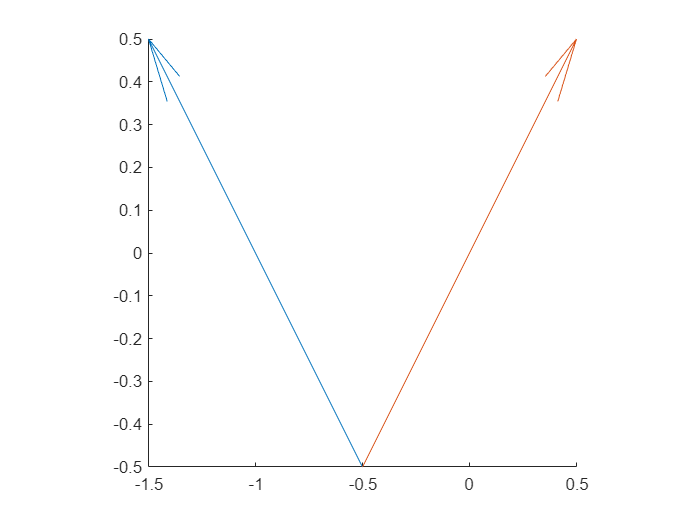

figure
% fcontour(F,[-1 1 -1 1])
axis('square')
hold on
quiver(-0.5,-0.5,V(1,1),V(1,2),0, 'MaxHeadSize',0.5)
quiver(-0.5,-0.5,V(2,1),V(2,2),0, 'MaxHeadSize',0.5)
hold off

Si consideramos:

2 / max(max(V))

$$ans = 2$$

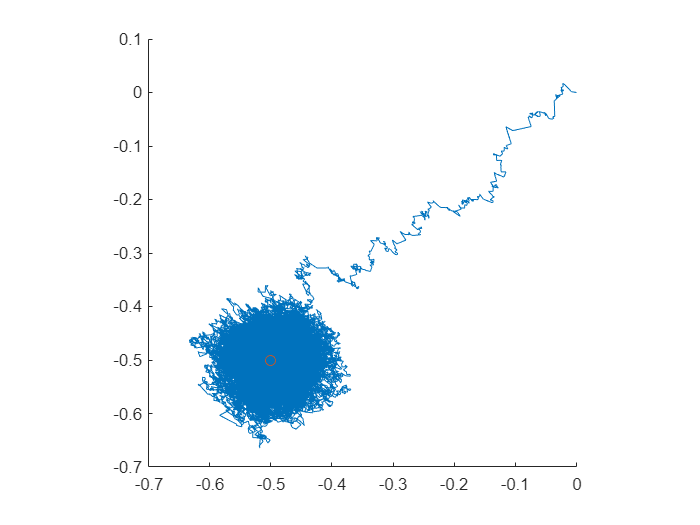

W0 = [0 0];
Mdl = arima('Constant',0,'AR',{-0.5 -0.5},'Variance',1.5);
rng(5)
sim = simulate(Mdl,1e5);
t = sim(3:end)';
p1 =sim(2:end-1)';
p2 = sim(1:end-2)';
p = [p1;p2];
alpha = 0.001;
[W,b] = adaline_epoca(W0,[0],alpha,p,t);
figure
% fcontour(F,[-1.5 1.5 -1.5 1.5])
axis('square')
hold on 
plot(W(1,:),W(2,:))
plot(-0.5,-0.5,'o')
hold off

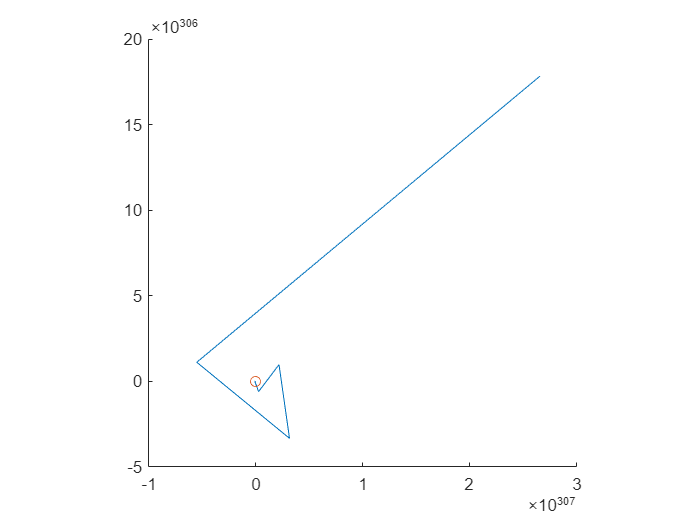

W0 = [0 0];
Mdl = arima('Constant',0,'AR',{-0.5 -0.5},'Variance',1.5);
rng(5)
sim = simulate(Mdl,1e5);
t = sim(3:end)';
p1 =sim(2:end-1)';
p2 = sim(1:end-2)';
p = [p1;p2];
alpha = 2;
[W,b] = adaline_epoca(W0,[0],alpha,p,t);
figure
% fcontour(F,[-1.5 1.5 -1.5 1.5])
axis('square')
hold on 
plot(W(1,:),W(2,:))
plot(-0.5,-0.5,'o')
hold off

function [W,b] = adaline_epoca(W0,b0,alpha, p,t,ba)
% ba = 1 activa la actualizción del bias
    if nargin > 5
      ba = ba;
    else
      ba = 0;
    end
    [fil,col] = size(p);
    W = [W0'];
    b = [b0'];
    for i = 1:col
        a = W0 * p(:,i) + b0;
        e = t(:,i)-a; 
        Wn = W0 + 2 * alpha * e * p(:,i)';
        
        if ba
            bn = b0 +  2 *alpha * e;
            b = [b bn'];
            b0 = bn;
        end
        
        W = [W Wn'];
        W0 = Wn;
    end
end